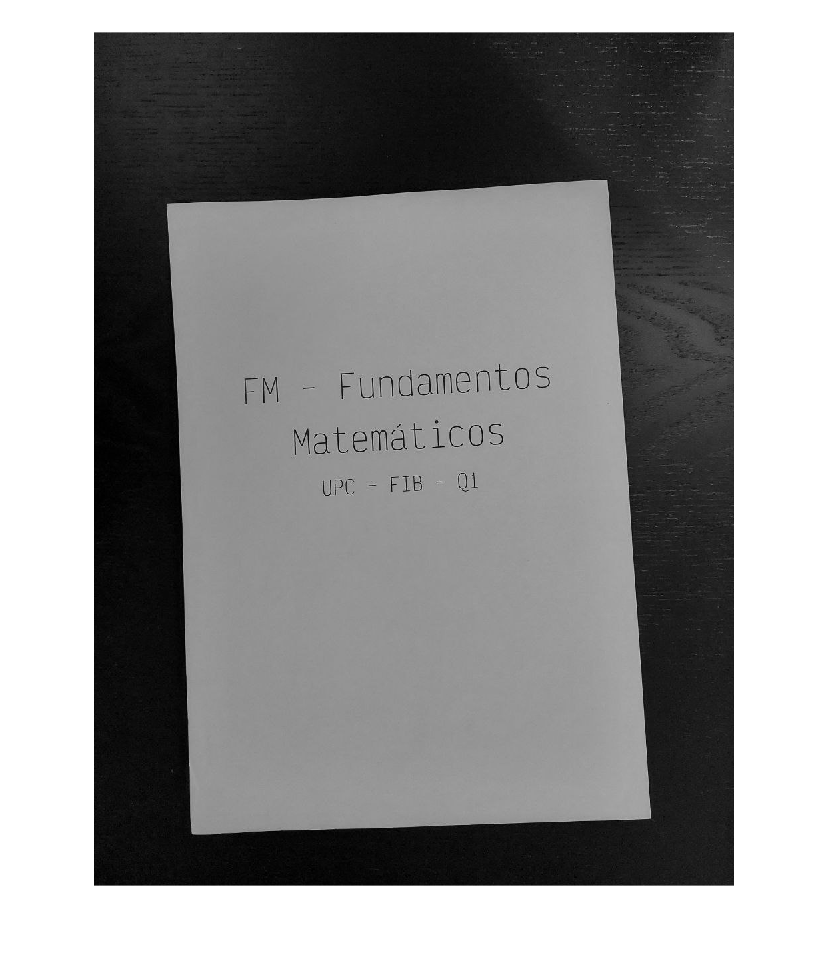

imagen_original = imread('foto1.jpeg');
imagen_grises = rgb2gray(imagen_original);
imshow(imagen_grises);

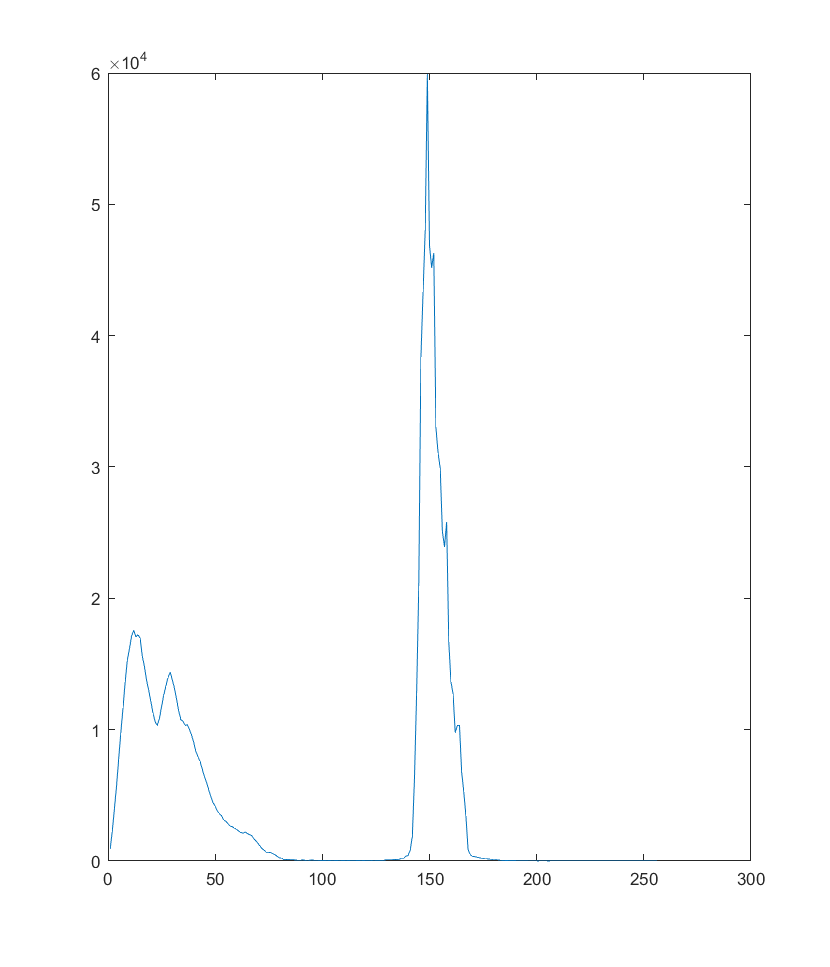

histogramas_grises = imhist(imagen_grises);
plot(histogramas_grises);

otsu = otsuthresh(histogramas_grises) * 255

otsu = 88

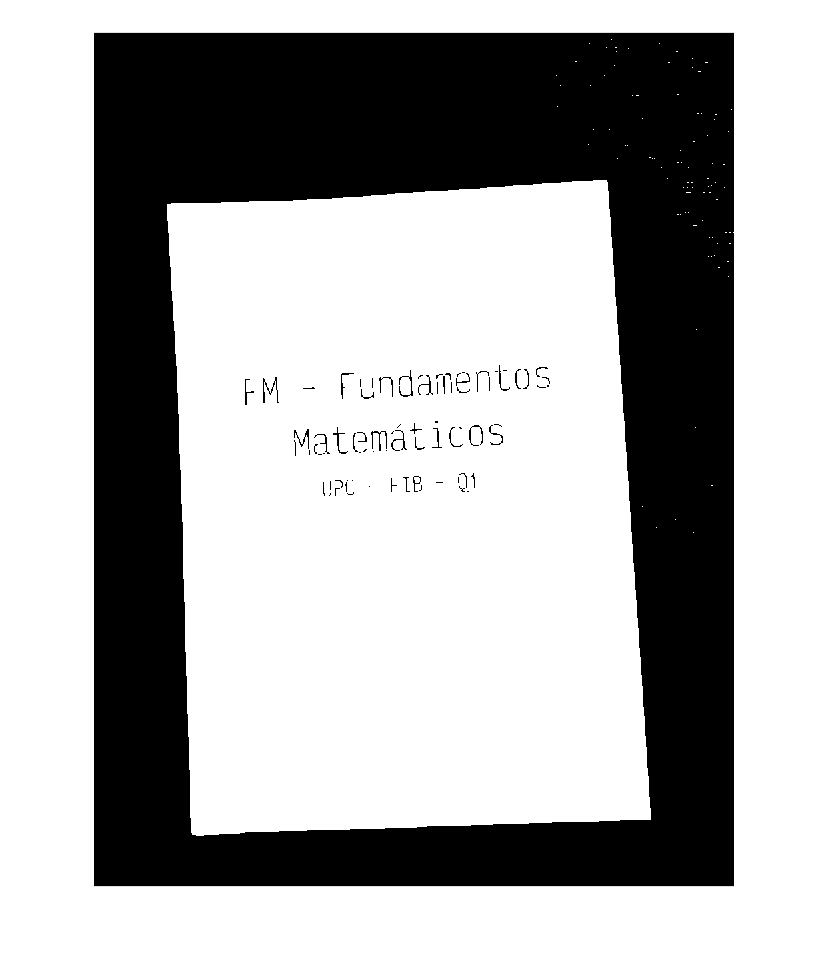

imagen_blanco_y_negro = imagen_grises > otsu;
imshow(imagen_blanco_y_negro);

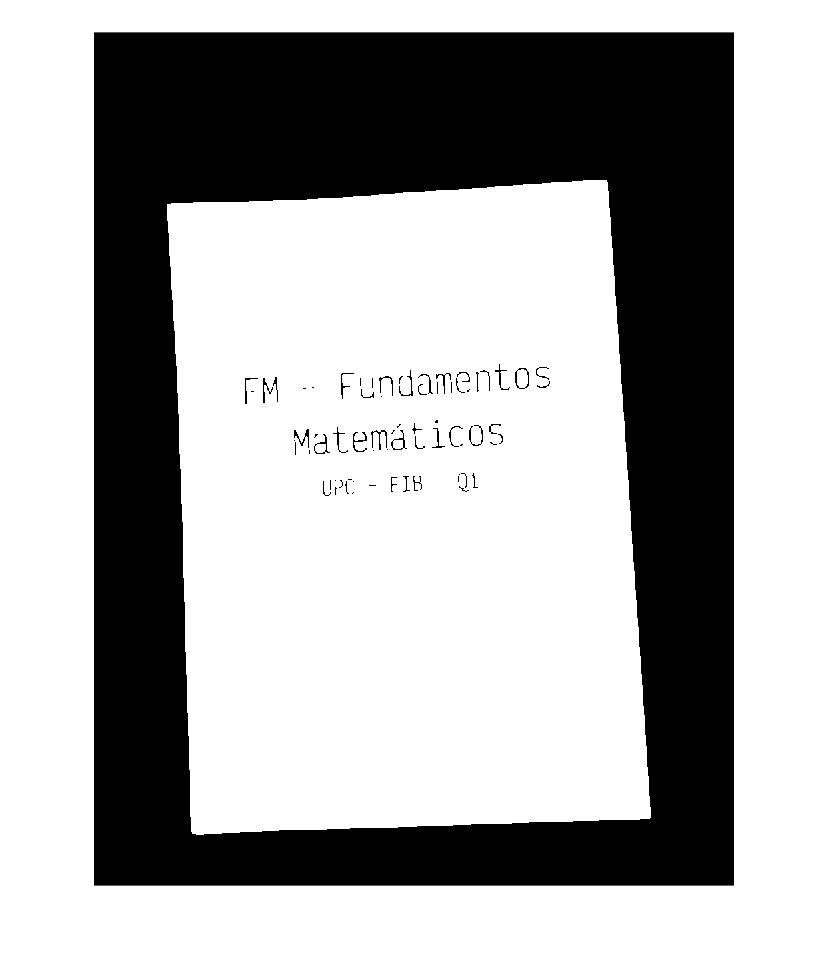

SE = strel('disk', 1);

imagen_abierta = imopen(imagen_blanco_y_negro, SE);
imshow(imagen_abierta);

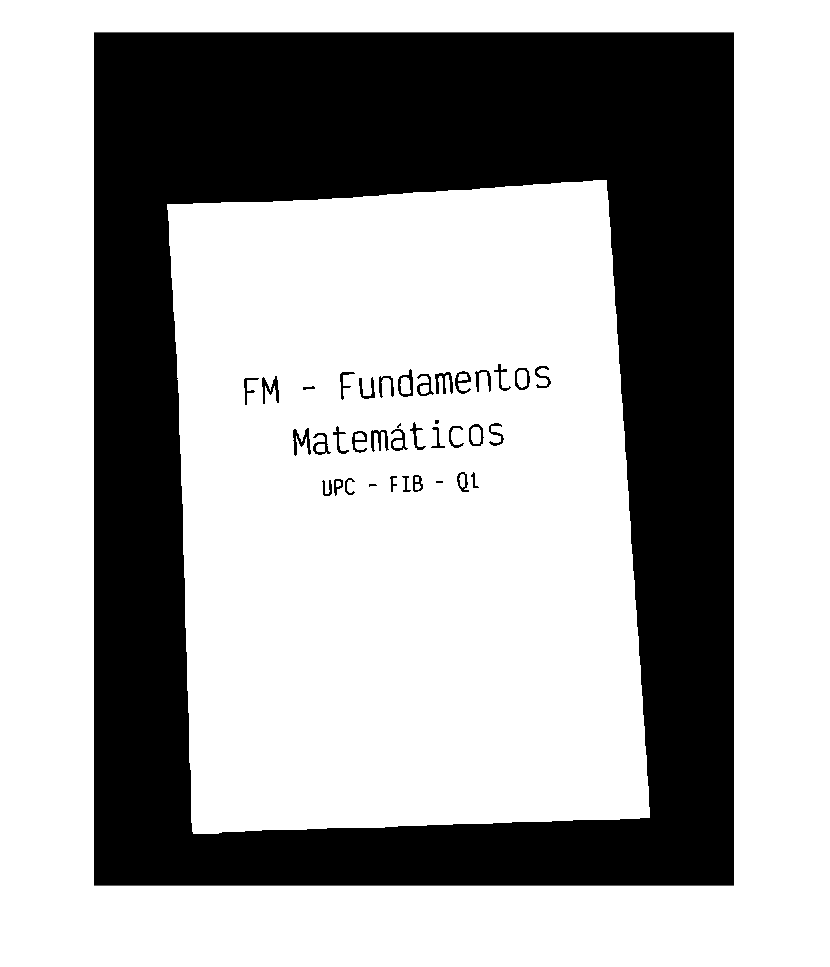

imagen_negada = ~imagen_abierta;
imagen_negada_dilatada = imdilate(imagen_negada, SE);
imagen_abierta_dilatada = ~imagen_negada_dilatada;
imshow(imagen_abierta_dilatada);

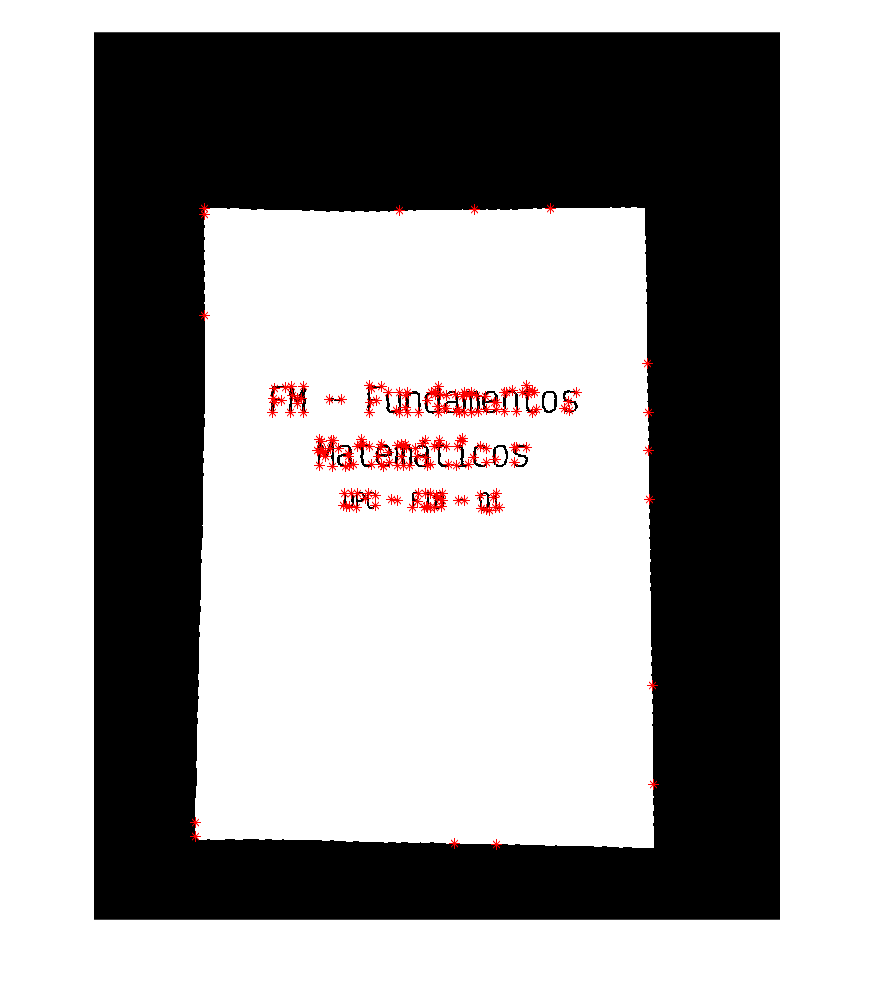

theta = rotacion(imagen_abierta_dilatada);
imagen_rotada = imrotate(imagen_abierta_dilatada, theta);

C = corner(imagen_rotada); 
imshow(imagen_rotada) 
hold on 
plot(C(:,1),C(:,2),'r*');
hold off

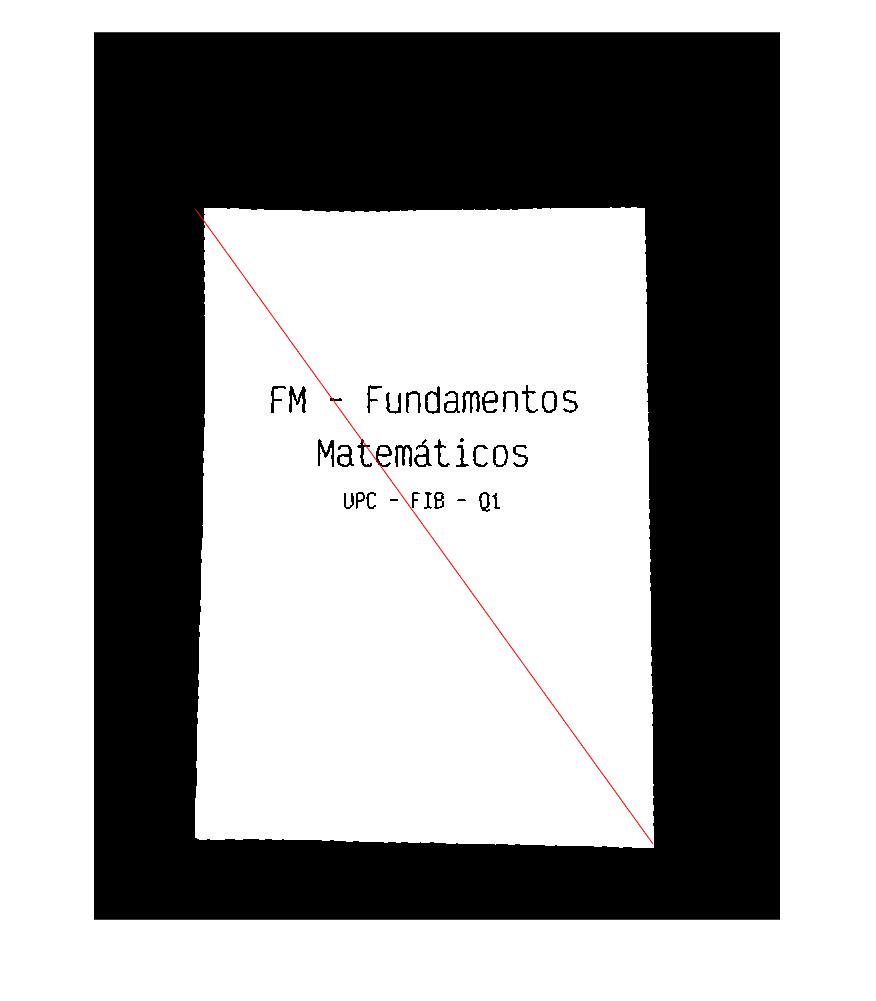


xmin = min(transpose(C(:, 1)));
ymin = min(transpose(C(:, 2)));
xmax = max(transpose(C(:, 1)));
ymax = max(transpose(C(:, 2)));

imshow(imagen_rotada)
hold on
plot([xmin, xmax], [ymin, ymax], 'r');
hold off

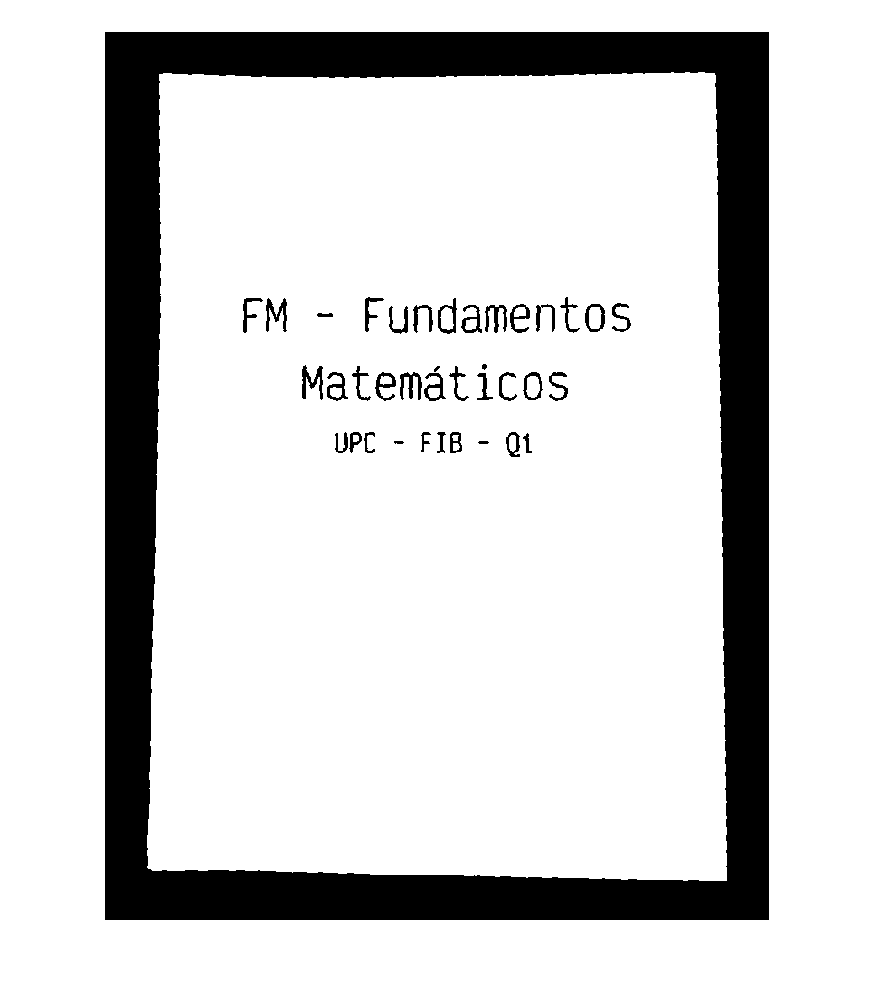

xmin = xmin -50;
xmax = xmax +50;
ymin = ymin -50;
ymax = ymax +50;
imagen_cortada = imcrop(imagen_rotada, [xmin ymin xmax-xmin ymax-ymin]);
imshow(imagen_cortada);

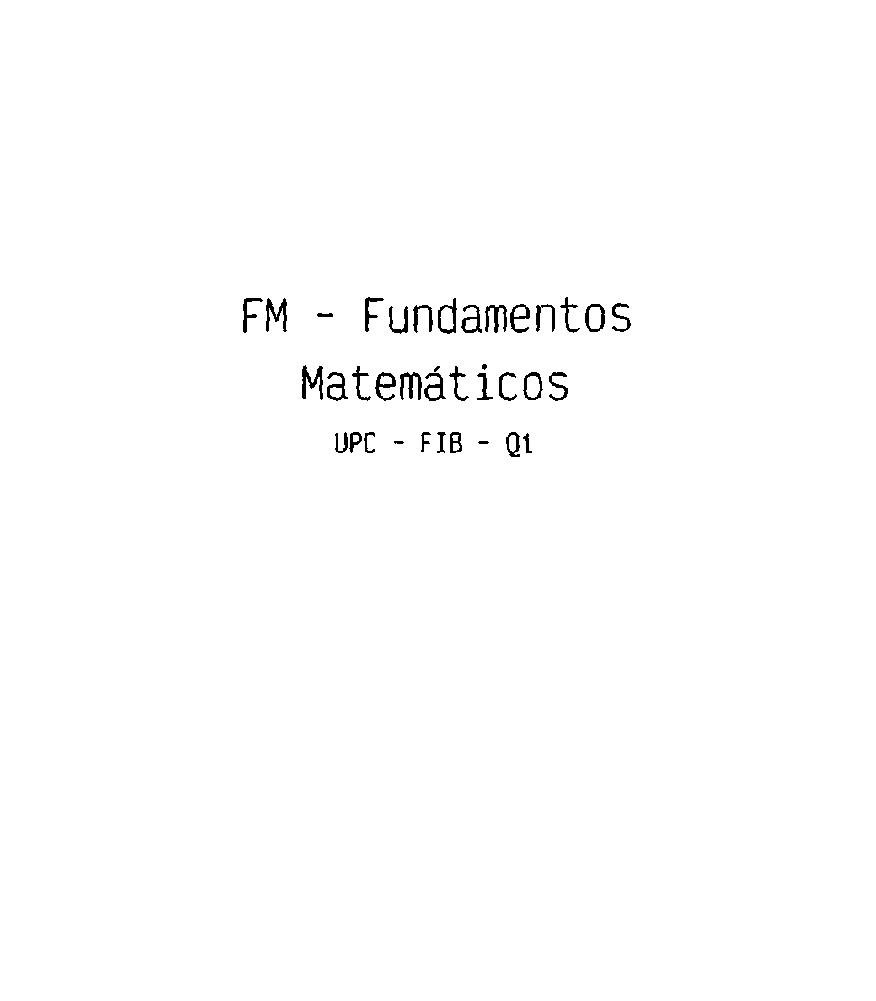

tamanoc = size(imagen_cortada);
copia_imagen_cortada = imagen_cortada;
resultado = imagen_cortada;

i = 1;
blanco = false;
while ~blanco && i < tamanoc(1)
    j = 1;
    while ~blanco && j < tamanoc(2)
        blanco = imagen_cortada(i, j);
        imagen_cortada(i, j) = 1;
        j = j + 1;
    end
    blanco = false;
    i = i + 1;
end

resultado = resultado | imagen_cortada;

imagen_cortada = copia_imagen_cortada;
i = tamanoc(1);
blanco = false;
while ~blanco && i >= 1
    j = tamanoc(2);
    while ~blanco && j >= 1
        blanco = imagen_cortada(i, j);
        imagen_cortada(i, j) = 1;
        j = j - 1;
    end
    blanco = false;
    i = i - 1;
end

resultado = resultado | imagen_cortada;

imagen_cortada = copia_imagen_cortada;

j = 1;
blanco = false;
while ~blanco && j < tamanoc(2)
    i = 1;
    while ~blanco && i < tamanoc(1)
        blanco = imagen_cortada(i, j);
        imagen_cortada(i, j) = 1;
        i = i + 1;
    end
    blanco = false;
    j = j + 1;
end

resultado = resultado | imagen_cortada;

imagen_cortada = copia_imagen_cortada;

j = tamanoc(2);
blanco = false;
while ~blanco && j >= 1
    i = tamanoc(1);
    while ~blanco && i >= 1
        blanco = imagen_cortada(i, j);
        imagen_cortada(i, j) = 1;
        i = i - 1;
    end
    blanco = false;
    j = j - 1;
end

resultado = resultado | imagen_cortada;

imagen_cortada = resultado;

%SE1 = [1, 1; 1, 1];
%imagen_cortada = ~imerode(~imagen_cortada, SE1);
%imagen_cortada = ~imdilate(~imagen_cortada, SE1);

imshow(imagen_cortada)

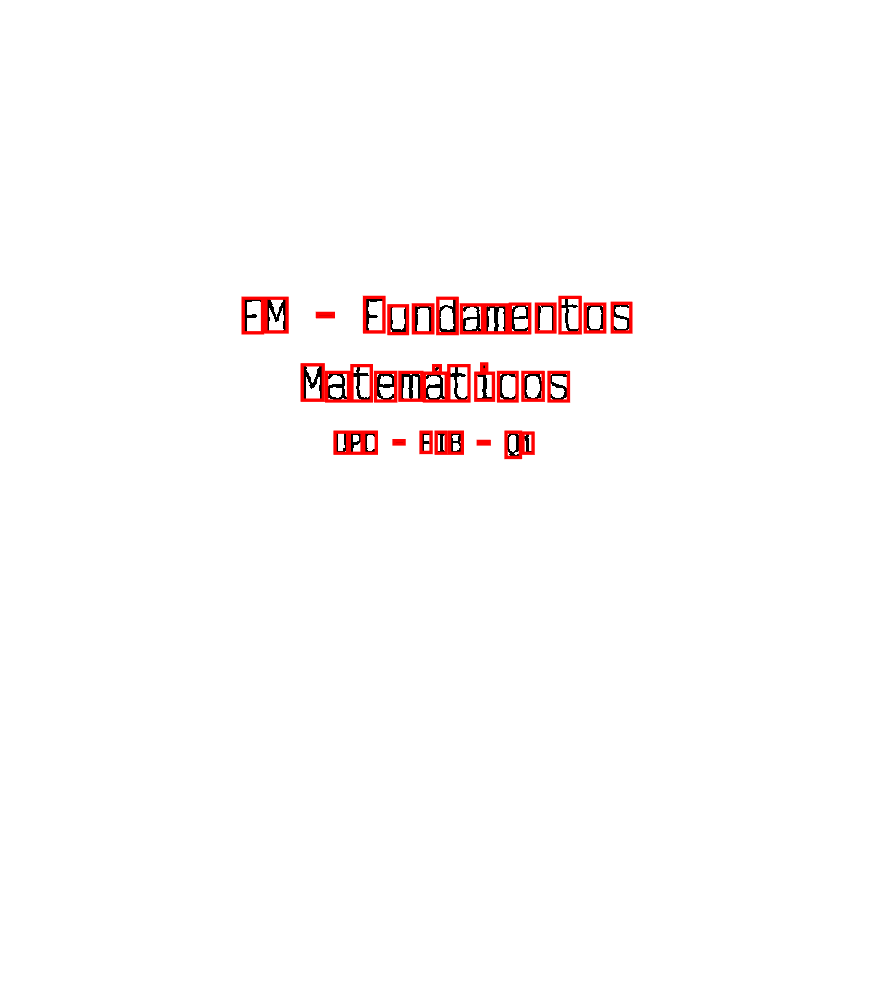


labeledImage = bwconncomp(~imagen_cortada);
			measurements = regionprops(labeledImage,'BoundingBox');
for k = 1 : length(measurements)
thisBB = measurements(k).BoundingBox;
rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],...
'EdgeColor','r','LineWidth',2 )
end

function theta = rotacion(imagen)
    [y, x] = find(imagen);
    
    nx = x - mean(x);
    ny = y - mean(y);
    
    nx = nx';
    ny = ny';
    
    c = cov(nx, ny);
    [evectors, evalues] = eig(c);
    
    [~, ind] = max(diag(evalues));
    
    theta = -pi/2-atan2(evectors(ind, 2), evectors(ind, 1));
end